flights=importFlightsData("flightsSep.csv");
flightsJFK=flights(flights.ORIGIN=="JFK",:);
flightsLGA=flights(flights.ORIGIN=="LGA",:);
summaryJFK=groupsummary(flightsJFK,"DESTINATION");
summaryLGA=groupsummary(flightsLGA,"DESTINATION");

%in the list named with task at the top we can find option called by join tables.

% Join tables
summaryNYC = innerjoin(summaryJFK,summaryLGA,"Keys","DESTINATION")

summaryNYC = 32×3 table
    DESTINATION    GroupCount_summaryJFK    GroupCount_summaryLGA
    ___________    _____________________    _____________________

        ATL                 181                      693         
        BNA                  30                      249         
        BOS                 423                      583         
        BTV                 113                       21         
        BUF                 245                       46         
        CHS                 121                       10         
        CLE                  31                      184         
        CLT                 226                      351         
        CMH                  37                       97         
        CVG                  29                       10         
        DCA                  38                      403         
        DEN    

%calculationg flights per day.
summaryNYC.GroupCount_summaryJFK(isnan(summaryNYC.GroupCount_summaryJFK))=0;
summaryNYC.GroupCount_summaryLGA(isnan(summaryNYC.GroupCount_summaryLGA))=0;
summaryNYC.TotalGroupCount=summaryNYC.GroupCount_summaryJFK+summaryNYC.GroupCount_summaryLGA;
%Then dividing the totalgroupcount by the number of days in our specified
%time period gives us the avarage number of flights per day
numberOfDays=days(max(flights.SCHEDULED_DEPARTURE_TIME)-min(flights.SCHEDULED_DEPARTURE_TIME));
summaryNYC.FlightsPerDay=ceil(summaryNYC.TotalGroupCount/numberOfDays)

summaryNYC = 32×5 table
    DESTINATION    GroupCount_summaryJFK    GroupCount_summaryLGA    TotalGroupCount    FlightsPerDay
    ___________    _____________________    _____________________    _______________    _____________

        ATL                 181                      693                   874               30      
        BNA                  30                      249                   279               10      
        BOS                 423                      583                  1006               34      
        BTV                 113                       21                   134                5      
        BUF                 245                       46                   291               10      
        CHS                 121                       10                   131             

airports=readtable("airports.csv");
airports.AIRPORT=categorical(airports.AIRPORT)

airports = 322×5 table
    AIRPORT            DISPLAY_AIRPORT_NAME               DISPLAY_AIRPORT_CITY_NAME_FULL      LATITUDE    LONGITUDE
    _______    _____________________________________    __________________________________    ________    _________

      ABE      {'Lehigh Valley International'      }    {'Allentown/Bethlehem/Easton, PA'}     40.655      -75.438 
      ABI      {'Abilene Regional'                 }    {'Abilene, TX'                   }     32.409       -99.68 
      ABQ      {'Albuquerque International Sunport'}    {'Albuquerque, NM'               }     35.042      -106.61 
      ABR      {'Aberdeen Regional'                }    {'Aberdeen, SD'                  }      45.45      -98.422 
      ABY      {'Southwest Georgia Regional'       }    {'Albany, GA'                    }     31.532      -84

destinations = join(summaryNYC,airports,"LeftKeys","DESTINATION",...
    "RightKeys","AIRPORT")

destinations = 32×9 table
    DESTINATION    GroupCount_summaryJFK    GroupCount_summaryLGA    TotalGroupCount    FlightsPerDay                 DISPLAY_AIRPORT_NAME                 DISPLAY_AIRPORT_CITY_NAME_FULL    LATITUDE    LONGITUDE
    ___________    _____________________    _____________________    _______________    _____________    ______________________________________________    ______________________________    ________    _________

        ATL                 181                      693                   874               30          {'Atlanta Municipal'                         }      {'Atlanta, GA'          }        33.641      -84.427 
        BNA                  30   

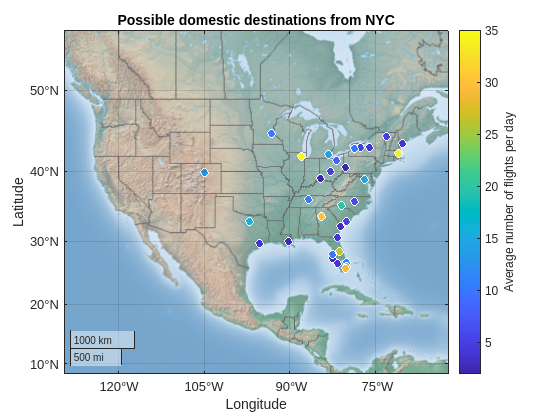

c =   ColorBar (Average number of flights per day) with properties:

    Location: 'eastoutside'
      Limits: [2 35]
    FontSize: 9
    Position: [0.8190 0.1095 0.0381 0.8167]
       Units: 'normalized'

  Show all properties


destinations=sortrows(destinations,"FlightsPerDay");
geoscatter(destinations.LATITUDE,destinations.LONGITUDE,[],destinations.FlightsPerDay,"filled","MarkerEdgeColor","w")
geolimits([8.2 56.2],[-128.9 -63.0]);
geobasemap colorterrain;
title("Possible domestic destinations from NYC")
c=colorbar;
c.Label.String="Average number of flights per day"